# Correlation in Electricity Usage

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code sets up the activity.

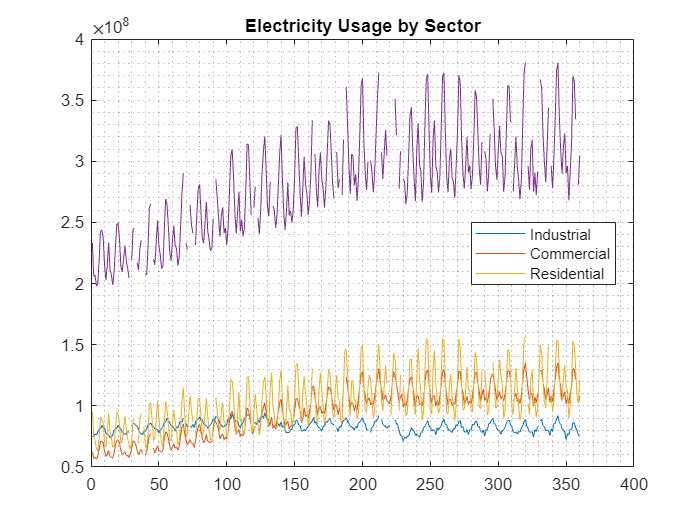

com = readmatrix("./data/electricity.xlsx", "Sheet", "com");
ind = readmatrix("./data/electricity.xlsx", "Sheet", "ind");
res = readmatrix("./data/electricity.xlsx", "Sheet", "res");
indV = ind(:);
comV = com(:);
resV = res(:);
usage = indV + comV + resV;
allSectors = [indV comV resV usage];
plot(allSectors)
grid minor
title("Electricity Usage by Sector")
legend("Industrial", "Commercial", "Residential",...
    "Location", "Best")

## Task 1

In this activity, you'll work with the same electricity usage data, but you might notice in the plot to the right that some of the values are missing.

By default, `corrcoef` returns a `NaN` if one of the data points is missing.  Specifying the `"Rows"` option to be `"complete"` ensures only sets of data without missing values are included in the calculation.

`corrcoef``(``A``,``B``,``"Rows"``,``"complete"``)`

comResCorr = corrcoef(com, res, "Rows", "complete")

comResCorr =     1.0000    0.8288
    0.8288    1.0000


## Task 2

What if you wanted to find the correlation coefficients between all the sectors at once?  Which sector best correlates with the total electricity usage?

The matrix `allSectors` contains the columns of electricity usage data for all of the sectors and the total usage.   You can also find the correlation coefficient matrix for the columns of a matrix by passing a single matrix to `corrcoef`.  

`corrcoef``(``M``,``"Rows"``,``"complete"``)`

allCorr = corrcoef(allSectors, "Rows", "complete")

allCorr =     1.0000    0.2035    0.2065    0.3139
    0.2035    1.0000    0.8286    0.9473
    0.2065    0.8286    1.0000    0.9548
    0.3139    0.9473    0.9548    1.0000
